# Exploring Nenana Ice Classic Data  

**Before you get started:**

This live script is intended to be used with the code hidden. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code **using the icon 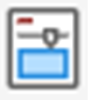 at the top right of the Live Editor pane.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running the code blocks in it.

  **Pro-tip**. The   **Run** command runs each line of code in order from the beginning until the last line in the script. You can clear the output in the script in the **View** tab by clicking **Clear all Output**.

## Introduction

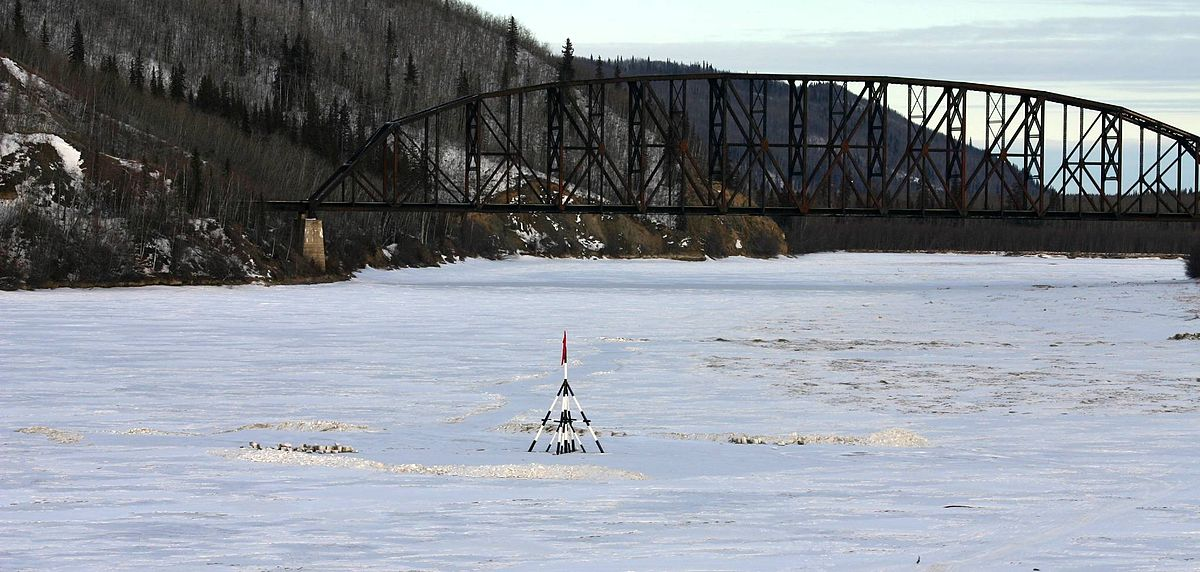

[https://commons.wikimedia.org/wiki/File:Tanana_River_in_Nenana.jpg](https://commons.wikimedia.org/wiki/File:Tanana_River_in_Nenana.jpg)

The Nenana Ice Classic is an annual event that takes place in Nenana, Alaska. It is a guessing game where people try to predict the exact time when the ice on the Tanana River will break up in the spring. 

Participants purchase tickets for a small fee and guess the month, day, hour, and minute when the tripod, which is placed on the frozen river, will move and stop the clock. The tripod is connected to a wire that is attached to a clock on the riverbank. When the ice starts to melt, the tripod moves with the current, and when it falls through the ice, the wire pulls a rope that stops the clock. 

You can find  the exact dates and times of ice breakup have been collected since 2017 and reported on a calendar in the [Nenana Ice Classic Brochure](https://www.nenanaakiceclassic.com/brochures) on the [Nenana Ice Classic Website](https://www.nenanaakiceclassic.com/). **Can you use the data of the exact dates and times of ice breakup from 1917-2021 to predict the exact time when the Tenana River will break? Can you use the data to determine impacts of climate change?**

 National Snow and Ice Data Center provides the tabulated version of the exact times of breakup in a .csv file from 1917 until 2021. A screenshot of the data follows:

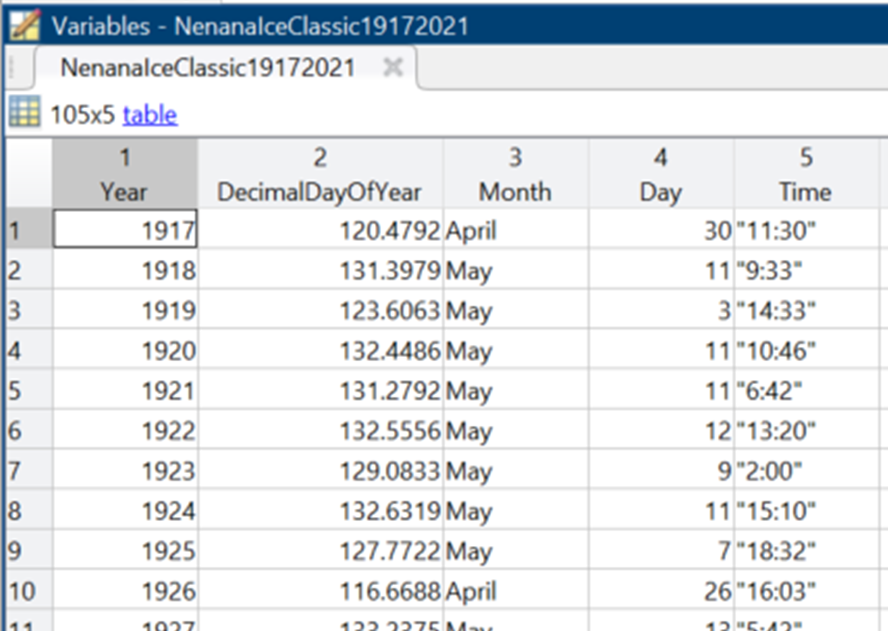

## 1. Import the Data

Press the 'Import Data' button below to import the data for the table of exact times from 1917-2021 of ice breakup on the Tanana River in Nenana, Alaska. 

% DO NOT MODIFY
 
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Year", "DecimalDayOfYear", "Month", "Day", "Time"];
opts.VariableTypes = ["double", "double", "categorical", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Time", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Month", "Time"], "EmptyFieldRule", "auto");

% Import the data
% %Nenana Ice Classic. Edited by W. N. Meier and C. F. Dewes. 2020. Nenana Ice Classic: Tanana 
% River Ice Annual Breakup Dates, Version 2. [1917-2021]. Boulder, Colorado USA. NASA 
% National Snow and Ice Data Center Distributed Active Archive Center. 
% https://doi.org/10.5067/CAQ58H42LQY2. April 26, 2023]

NenanaIceClassic19172021 = readtable("NenanaIceClassic_1917-2021.csv", opts)
% Change here the path to the file so the live script can be compatible
% with MATLAB Online too
Year=NenanaIceClassic19172021.Year;
DecimalDayOfYear=NenanaIceClassic19172021.DecimalDayOfYear;



 **Reflect**. 

Scroll through the data over the years to identify trends. You can go to each column in the table to sort the data. Is there a month, day or time that appears in the data most often?  

##  

## 2. Create a Linear Model for Data 

Below, press the  'Plot & Fit Data', and you will see the breakup data from 1917 - 2021 plotted as DecimalDayOfYear by Year. The fit line is displayed on the graph. 

% DO NOT MODIFY
 
% Fit: "All Data - 1917-2021".
[xData, yData] = prepareCurveData( Year, DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( "poly1" );

% Fit model to data.
[fitresult, ~] = fit( xData, yData, ft );

% Plot fit with data.

h = plot( fitresult, xData, yData);
title("1917 - 2021")
legend( h, "DecimalDayOfYear vs. Year", "Fitted Curve", "Location", "best", "Interpreter", "none" );
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );



## 3. Use Fit Line to Predict Future Breakup Times

### ** Exercise A. Predict Future Breakup Time for 2023 **

The equation for the fit line for the 1917-2021 data is **y=-0.0861∗x+294.0545**. The actual breakup time for 2023 was May 2, 6:47pm (122.76 Decimal Day of Year). You can plot this value along with your prediction by pressing the 'Plot data with 2023 prediction' button below. 

% Slope of fit= mfit#
 

mfit=fitresult.p1;

%y-intercept of fit=bfit#
bfit=fitresult.p2;
y1=mfit*2023+bfit;

plot(fitresult, xData, yData)

hold on
scatter(2023,y1, 20,"magenta","filled")
legend("Data","Fitted Curve","Predicted Value")
title("1917-2021+ 2023 Prediction");
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );

hold off
disp("1917 - 2021 Data with the Predicted 2023 value")

Based on your best fit line for the 1917-2021 data, calculate the error between your best fit line prediction and the 2023 breakup date and time of May 2, 6:47pm (122.76 Decimal Day of Year) by pressing the 'Calculate error between your prediction and the actual breakup time' button. 

% You can remove this section.
 
errory1=122.76-y1; 
errory1=(errory1/122.76)*100;

% Format the number with two decimal places using num2str
formatted_str = num2str(errory1, '%.2f');

% Convert the formatted string to a numeric value (optional)
formatted_num = str2double(formatted_str);

% Display the formatted string and the numeric value
% disp(['Formatted String: ', formatted_str]);
% disp(['Formatted Number: ', num2str(formatted_num)]);
disp("The error between the actual time of breakup in 2023 and the value" + newline + "predicted for 2023 by the fit for all data  is "+  formatted_str + " %")


 **Reflect**. 

    How close or far off is the actual breakup time of 2023 from your predicted value? Why might the value be so close or far off?  

###  **Exercise B. Predict Future Breakup Time for 2033 **

Use the fit and the slider below to determine the prediction for the 2033 breakup time.

% If you remove this section, remove every section in Exercise B. 
predyr=2033;
Predyr_Fit=mfit*predyr+bfit;

% Input the decimal day of the year and the year
decimalDay = Predyr_Fit;
specifiedYear = predyr;

% Create a datetime object using the specified year and decimal day
dt = datetime(specifiedYear, 1, 1) + days(decimalDay);

% Convert the datetime to the desired format
formattedDate = string(dt, 'MM/dd/yyyy HH:mm:ss');
disp("Based on the fit for 1917 - 2021, ice will breakup in "+ predyr+ ", on " + formattedDate + " , which is " + decimalDay + " in DecimalDayofyears")

% Display the result
% disp(formattedDate);

% 


% Plot fit with data with predicted value for 2033.

 

plot(fitresult, xData, yData)
hold on
scatter(predyr,Predyr_Fit, 20,"magenta","filled")
legend("Data","Fitted Curve","Predicted Value")
title("1917 - 2021 & Prediction for " + predyr);
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );
hold off


 **Reflect**.  Visually inspect the graphs to determine if, based on the previous trends, this is a reasonable prediction.

## 4. Use Fit Line to Evaluate Past Breakup Trends

Look at the scatter plot of the data again. One linear fit for the entire 1917-2021 range of data may not make sense because there may be multiple trends over the time range. The different trends in the Nenana Ice Classic data for ice breakup times happen because of a few reasons:

- **Weather Changes:** The weather can be warmer or colder from year to year, and this affects when the ice on the river melts. Warmer years make the ice break earlier, while colder years make it break later.

- **Natural Differences: **Things like how much snow there is, how fast the river flows, and other natural stuff can change every year. These differences can make the ice breakup times go up and down without following a clear pattern.

- **Sometimes It's Just Luck:** Imagine flipping a coin. Sometimes you might get heads a few times in a row, and then you might get tails. It's like that with the ice breakup dates too. Sometimes it seems like there's a trend when it's actually just random luck.

- **Nature Can Be Tricky:** Ice melting can be influenced by many complicated things that don't always follow a simple pattern. This can make the ice breakup dates unpredictable.

- **Data Changes:** How people record the ice breakup dates might have changed over the years. This can make the data less consistent and harder to analyze.

So, when you see that the latest ice breakups are mostly in the early years and the earliest ones are in the later years, it's because of these reasons. It's not always easy to predict when the ice will break because nature can be unpredictable.

 **Reflect**.  

        Which date ranges seem to indicate positive slopes or negative slopes?

In the next three exercises, you will select three ranges of dates to explore past breakup trends. 

### ** Exercise A. Create a fit by choosing a first range of dates. **

Use the slider below to first select the Start Date and the End Date of your data range. 

% If you remove this section, remove every section in Exercise A. 
% Fit: "Data Range 2".
[xData, yData] = prepareCurveData(Year,DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( "poly1" );
bds = sort([1995, 2012]);
 rangestart2=bds(1);
 rangeend2= bds(2);


Adjust the sliders for the Start Date, the End Date, and then press the 'Plot fit for first set of data ranges' to plot the new set of start to end dates. All of the data from 1917 - 2021 will be plotted, but the date range you have selected  will be shown as blue circles while the excluded data will be plotted and shown as green plus signs.  

 
excludedPoints = (xData<rangestart2) | (xData>rangeend2) ;
opts = fitoptions( "Method", "LinearLeastSquares" );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult2, ~] = fit( xData, yData, ft, opts );

% Plot fit with data.


h = plot( fitresult2, xData, yData, excludedPoints );
title("Date Range " + rangestart2 + "-" + rangeend2);
legend( h, "DecimalDayOfYear vs. Year", "Excluded DecimalDayOfYear vs. Year", "Fitted Curve for Date Range " + rangestart2 + " - " + rangeend2, "Location", "SouthWest", "Interpreter", "none" );
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );


### ** Exercise B. Create a fit by choosing a second range of dates. **

Adjust the sliders for the Start Date, the End Date, and then press the 'Plot fit for second set of data ranges' to plot the new set of start to end dates.  All of the data from 1917 - 2021 will be plotted, but the date range you have selected will be shown as blue circles while the excluded data will be plotted and shown as green plus signs. 

% If you remove this section, remove every section in Exercise B. 
% Fit: "Data Range 3".
[xData, yData] = prepareCurveData(Year,DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( "poly1" );
bdsb = sort([1976, 2000]);
rangestart3= bdsb(1);
rangeend3= bdsb(2);

 
excludedPoints = (xData<rangestart3) | (xData>rangeend3) ;
opts = fitoptions( "Method", "LinearLeastSquares" );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult3, ~] = fit( xData, yData, ft, opts );

% Plot fit with data.
h = plot( fitresult3, xData, yData, excludedPoints );
title("Date Range " + rangestart3 + "-" + rangeend3);
legend( h, "DecimalDayOfYear vs. Year", "Excluded DecimalDayOfYear vs. Year", "Fitted Curve for Date Range " + rangestart3 + " - " + rangeend3, "Location", "SouthWest", "Interpreter", "none" );
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );



### ** Exercise C. Create a fit by choosing a third range of dates. **

Adjust the sliders for the Start Date, the End Date, and then press the 'Plot fit for third set of data ranges' to plot the new set of start to end dates.  All of the data from 1917 - 2021 will be plotted, but the date range you have selected will be shown as blue circles while the excluded data will be plotted and shown as green plus signs. 

% If you remove this section, remove every section in Exercise C. 
% Fit: "Data Range 4".
[xData, yData] = prepareCurveData(Year,DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( "poly1" );
bdsc = sort([1946,2021]);
rangestart4 = bdsc(1);
rangeend4 = bdsc(2);

 
excludedPoints = (xData<rangestart4) | (xData>rangeend4) ;
opts = fitoptions( "Method", "LinearLeastSquares" );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult4, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
h = plot( fitresult4, xData, yData, excludedPoints );
title("Date Range " + rangestart4 + "-" + rangeend4);
legend( h, "DecimalDayOfYear vs. Year", "Excluded DecimalDayOfYear vs. Year", "Fitted Curve for Date Range " + rangestart4 + "-" + rangeend4, "Location", "SouthWest", "Interpreter", "none" );
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );

%%


### ** Exercise D. Compare Slopes to quantify the rate of change of the ice breakup times. **

Press the 'Calculate slopes for all date ranges' button to compare slopes of a variety of date ranges including the complete 1917 - 2021 range of dates to determine if there is sufficient evidence of the changing climate. 

 **Reflect**.  

Calculate the slopes of your new dates ranges (exercises A - C), and of the linear fit the full date range (1917-2021). How do these slopes compare? Is the slope always negative?

% If you remove this section, remove every section in Exercise D. 
 
m_datarange_1=fitresult.p1;
m_datarange_2=fitresult2.p1;
m_datarange_3=fitresult3.p1;
m_datarange_4=fitresult4.p1;

Slopes= [m_datarange_1,m_datarange_2,m_datarange_3,m_datarange_4]';
Start_year=[1917,rangestart2,rangestart3,rangestart4]';
End_year=[2021,rangeend2,rangeend3,rangeend4]';
Table_of_Slopes=table(Start_year,End_year,Slopes)


Sort table by values of slope by choosing ascending or descending  from the dropdown menu. Is there a trend in the slope that shows evidence of the changing climate?

Sorted_Table=sortrows(Table_of_Slopes,{'Slopes'},{'descend'})
disp('Table sorted by slopes')

You can also sort the table by values of start date by choosing ascending or descending from the dropdown menu. Is there a trend in the start year that shows evidence of the changing climate?

Sorted_Table_yr=sortrows(Table_of_Slopes,{'Start_year'},{'descend'})
disp('Table sorted by start year')

 **Reflect**.  

-         After comparing the scatter plot and slopes of the data over various ranges, does one linear fit for the entire 1917-2021 range of data make sense? 

-         Why might there be multiple trends over this 1917-2021 time range? 

To explore this topic further, read [Nenana Ice Classic: Breaking up is hard to do predictably | National Snow and Ice Data Center (nsidc.org)](https://nsidc.org/news-analyses/news-stories/nenana-ice-classic-breaking-hard-do-predictably)

% Clear temporary variables
clear opts
